inputSize = trainedNetwork.Layers(1).InputSize;
path = '/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/231003_ファイバー簡略化/分類用画像/3秒間隔_image';
I=imageDatastore(path,"IncludeSubfolders",true,"LabelSource","foldernames");
% I=imageDatastore('C:\Users\daikidaiku\Box\Personal\study\Data\2023\231003_ファイバー簡略化\分類用画像\3秒間隔_image',...
%     "IncludeSubfolders",true,"LabelSource","foldernames")
% type=readcell("/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/研究/230117/type.xlsx")


% n=type(2:5,4);
% m=repelem(n,55); % 繰り返し
p=I.Labels;

I.Labels=p;
[imdsTrain, imdsValidation] = splitEachLabel(I,0.7,"randomized");
Im = augmentedImageDatastore(inputSize,imdsValidation);
YTest = classify(trainedNetwork,Im);
figure;

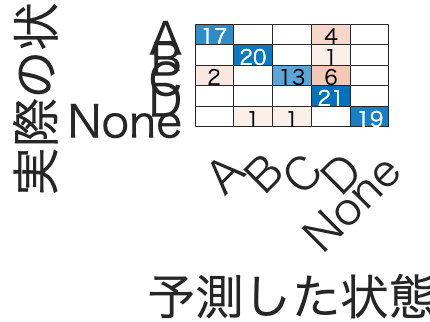

c=imdsValidation.Labels;
cm=confusionchart(c,YTest);
cm.FontSize=22;
xlabel('予測した状態')
ylabel('実際の状態')

c;
YTest;
mistake = {};
a = c == YTest;
for i = 1:length(a)
    if a(i) == 0
        imdsValidation.Files{i,1}
        c(i)
        YTest(i)
        predict(i,trainedNetwork)
    end
end

ans = '/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/231003_ファイバー簡略化/分類用画像/3秒間隔_image/A/02_27.jpg'

ans = categorical
     A 


ans = categorical
     D 


この型の変数ではドット インデックスはサポートされていません。

エラー: SeriesNetwork/predict (行 320)
            Y = this.UnderlyingDAGNetwork.predict(X, varargin{:});

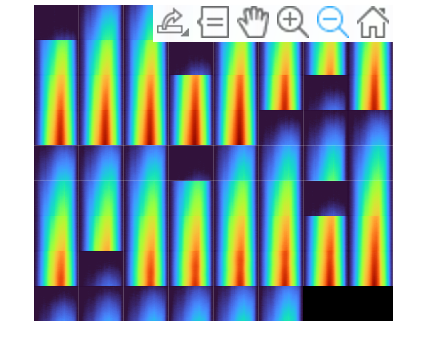

I =imageDatastore('/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/231003_ファイバー簡略化/分類用画像/3秒間隔_image/D');
montage(I)

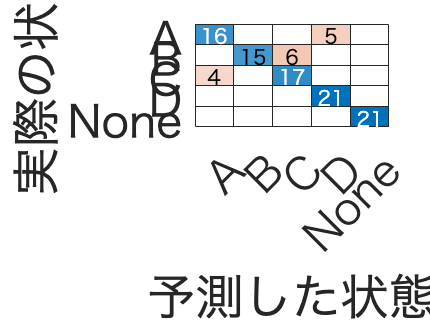


cm=confusionchart(matrixForValidationData, truePredictedLabelsForValidation);
cm.FontSize=22;
xlabel('予測した状態')
ylabel('実際の状態')